clear;clc;
%定义变量
format long
EV_position1=rand(2,25).*8;
EV_position2=7+rand(2,25).*8;
% 生成第一行的随机数组，范围在15到20之间
first_row = 7 + (22-14) * rand(1, 25);
% 生成第二行的随机数组，范围在0到5之间
second_row = 0 + (8-0) * rand(1, 25);
% 将两行数组合并成一个 2x25 的数组
EV_position3 = [first_row; second_row];
% 生成第一行的随机数组，范围在15到20之间
first_row = 0 + (22-14) * rand(1, 25);
% 生成第二行的随机数组，范围在0到5之间
second_row = 7 + (8-0) * rand(1, 25);
% 将两行数组合并成一个 2x25 的数组
EV_position4 = [first_row; second_row];
EV_position=[ EV_position1,EV_position4,EV_position3,EV_position2];%电动汽车的位置
EV_SOC_0=rand(1,100).*0.5+0.2;%电动汽车的SOC初始值，在0.2到0.9之间
CS_position=[0 0 15 15;0 15 0 15];%充电站的位置
DT=1:45;
eta_PV = 0.4; % 光伏效率
P_mpp = 500; % 光伏最大功率点功率，假设为20
% 变量 光照强度矩阵，假设随正态分布变化
Irr = zeros(length(CS_position), length(DT)); 
for i=1:length(CS_position)
rng(0);
% 定义正态分布的均值和标准差
mu = 20; % 均值
sigma = 50; % 标准差
% 生成10个正态分布随机数
Irr(i,:) = 50*normpdf(1: length(DT),mu, sigma);
end
f_temp = rand(length(CS_position), length(DT)); % 变量 温度函数矩阵，假设为随机值
for i=1:length(CS_position)
rng(0);
% 定义正态分布的均值和标准差
mu = 20; % 均值
sigma = 100; % 标准差
% 生成10个正态分布随机数
f_temp(i,:) = 50*normpdf(1: length(DT),mu, sigma);
end
% 计算光伏注入功率 P_PV
n=[20,100,80,90];

P_PV = zeros(length(CS_position), length(DT));
for s = 1:length(CS_position)
    for t = 1:length(DT)
        P_PV(s, t) =n(s)* eta_PV * P_mpp * Irr(s, t) * f_temp(s, t);
    end
end

% % 
% % 设置优化参数和初始值
% max_iteration=20;                                                       %最大迭代次数
% n=100;                                                                  %粒子数
% w = 0.7;                                                                % 惯性权重
% c1 = 1.5;                                                               % 学习因子1
% c2 = 1.5;                                                               % 学习因子2
% velocity_max = 4;                                                       % 最大速度限制
% position_min = [0 0 0 0];                                                 % 变量下界
% position_max = [11 11 11 11];                                              % 变量上界
% position = rand(n,4).*(position_max - position_min) + position_min;     % 初始化粒子位置
% velocity = rand(n,4);                                                   % 初始化粒子速度
% personalbest = position;                                                % 个体最优位置
% personalbest_val = zeros(n,1);                                          % 个体最优利润值
% 
% for i = 1:n
%     personalbest_val(i) = optimization(personalbest(i,:),EV_position,CS_position,EV_SOC_0,P_PV);             % 计算个体最优利润值
%     [fitness] = optimization(personalbest(i,:),EV_position,CS_position,EV_SOC_0,P_PV);  
% end
% 
% globalbest_val = max(personalbest_val);                                 % 全局最优利润值
% globalbest = personalbest(personalbest_val == globalbest_val,:);        % 全局最优位置
% 
% % 迭代优化
% start_time = tic;           % 记录程序开始时间
% for iter = 1:max_iteration
% %     生成速度
%     velocity = w.*velocity + c1.*rand(n,4).*(personalbest - position) + c2.*rand(n,4).*(globalbest - position);
% %     限制粒子速度范围
%     velocity = min(velocity,velocity_max);  
% %     更新位置
%     position = position + velocity;
% %     限制粒子位置范围
%     position = max(position,position_min);  
%     position = min(position,position_max);
% %     更新个体最优解
%     for i = 1:n
%         val= optimization(position(i,:),EV_position,CS_position,EV_SOC_0,P_PV);
%         if val > personalbest_val(i) 
%             personalbest(i,:) = position(i,:);
%             personalbest_val(i) = val;
%         end
%     end
% 
% %     更新全局最优解
%     [val,idx] = max(personalbest_val);
%     if val > globalbest_val
%         globalbest_val = val;
%         globalbest = personalbest(idx,:);
%     end
% %     disp(['Iteration ', num2str(iter)*matlab:matlab.internal.language.introspective.errorDocCallback('horzcat'), ': Best Fitness = ', num2str(globalbest_val),'Best Position =',num2str(globalbest)]);
% 
% %     显示进度条和预计剩余时间
%     elapsed_time = toc(start_time);
%     remaining_time = elapsed_time * (max_iteration - iter) / iter;
%     progress = iter / max_iteration * 100;
%     fprintf('进度: %3.0f%%，预计剩余时间：%s\r', progress, datestr(seconds(remaining_time), 'HH:MM:SS'));
% end
incentives3=[5.34551594436518	5.87095843597062	5.69415961323042	5.71775131199249];
[fitness,EV_SOC_F,SOC_time,P_EV,u_s,income,sigma,P_dso] = optimization(incentives3,EV_position,CS_position,EV_SOC_0,P_PV);  

Constraint 7: 1
Constraint 8: 1


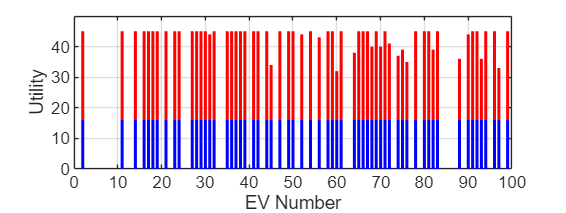

 figtime(SOC_time);

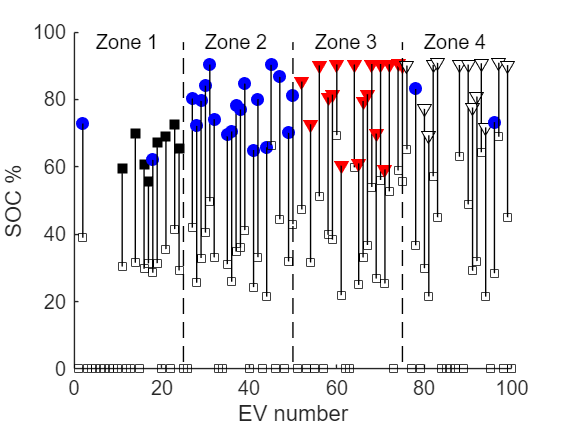

figure('visible', 'off');
figtime(SOC_time);
saveas(gcf, 'C:\Users\12442\Desktop\EV_Charge\EV_Charge/myplot113.png');
figure('visible', 'off');
figsoc(EV_SOC_0,EV_SOC_F,u_s);
saveas(gcf, 'C:\Users\12442\Desktop\EV_Charge\EV_Charge/myplot114.png');

figure('visible', 'off');
Figpower(P_EV);
saveas(gcf, 'C:\Users\12442\Desktop\EV_Charge\EV_Charge/myplot115.png');
figure('visible', 'off');
Figpower(P_PV);
saveas(gcf, 'C:\Users\12442\Desktop\EV_Charge\EV_Charge/myplot116.png');
 figsoc(EV_SOC_0,EV_SOC_F,u_s);

  fprintf('激励1,激励2,激励3');

激励1,激励2,激励3

 for s=1:4
 fprintf(' %0.1f%     ',incentives3(s) );
  end

 5.3 5.9 5.7 5.7

 fprintf('总利润： %0.01f%',income);

总利润： 2798182.9

% % %  Figpower(P_EV);
% % %  Figpower(P_PV);
fprintf('\n');  % 结束进度条
